# **Understanding COVID-19 from Research Articles using Text Analytics in MATLAB**

The data used for this analysis is available to download from [Semantic Scholar](https://pages.semanticscholar.org/coronavirus-research). 

## Read comm_use_subset papers

Download, save and extract the data in a local folder. Next, we will parse the content and save it as a table.

clear all
clc
dataFolder = ".\comm_use_subset\comm_use_subset\"; 
fds = fileDatastore(dataFolder,...
    "FileExtensions",".json",...
    "IncludeSubfolders",true,...
    "ReadFcn",@extractPaperContents,...
    "UniformRead",true);
t = readall(fds);
save('comm.mat', 't'); % store data for future analysis
% load comm.mat % load data if saved previously

## Explore the titles and abstract

Explore the titles and abstracts of the articles using wordcloud after pre-processing the data.

tdt = preprocessText(t.Title);
figure
wordcloud(tdt)

ans =   WordCloudChart with properties:

           WordData: [1×12371 string]
           SizeData: [1×12371 double]
    MaxDisplayWords: 100

  Show all properties


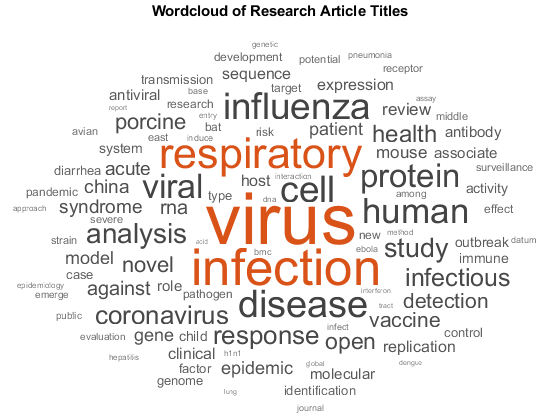

title('Wordcloud of Research Article Titles')
saveas(gcf, "Wordcloud_Titles.png");

tda = preprocessText(t.Abstract);
figure
wordcloud(tda)

ans =   WordCloudChart with properties:

           WordData: [1×60154 string]
           SizeData: [1×60154 double]
    MaxDisplayWords: 100

  Show all properties


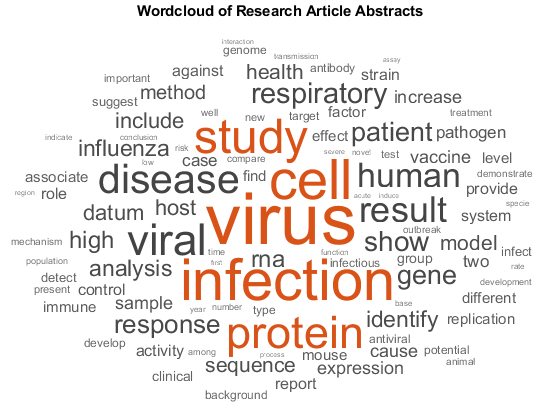

title('Wordcloud of Research Article Abstracts')
saveas(gcf, "Wordcloud_Abstracts.png");

## Create Bag-of-Words model

rng('default') % setting random number seed for reproducibility
numDocuments = numel(tda);
cvp = cvpartition(numDocuments,'HoldOut',0.2); % setting aside 20% for validation
documentsTrain = tda(cvp.training);
documentsValidation = tda(cvp.test);

bag = bagOfWords(documentsTrain);
bag = removeInfrequentWords(bag,2);
[bag,docsRemoved] = removeEmptyDocuments(bag); 

validationData = bagOfWords(documentsValidation);

### Create Topic Model

We will use Latent Dirichlet Allocation (LDA) method for creating a topic model. But first, we will test different solvers by comparing the goodness of fit and the time taken to fit the model. We will evaluate the goodness-of-fit of an LDA model by calculating the perplexity of a held-out set of documents.The perplexity indicates how well the model describes a set of documents. A lower perplexity suggests a better fit.

#### ***Test LDA Solvers***

numObservations = bag.NumDocuments;
solvers = ["cgs" "avb" "cvb0" "savb"]; 
numTopics = 20;
lineSpecs = ["+-" "*-" "x-" "o-"];
figure
for i = 1:numel(solvers)
    i
    solver = solvers(i);
    lineSpec = lineSpecs(i);
    
    if solver == "savb"
        numIterationsPerDataPass = ceil(numObservations/1000);
    else
        numIterationsPerDataPass = 1;
    end
    mdl = fitlda(bag,numTopics, ...
        'Solver',solver, ...
        'InitialTopicConcentration',1, ...
        'FitTopicConcentration',false, ...
        'ValidationData',validationData, ...
        'ValidationFrequency',numIterationsPerDataPass, ...
        'Verbose',0);
    
    history = mdl.FitInfo.History;
    
    timeElapsed = history.TimeSinceStart;
    validationPerplexity = history.ValidationPerplexity;
    
    % Remove NaNs.
    idx = isnan(validationPerplexity);
    timeElapsed(idx) = [];
    validationPerplexity(idx) = [];
    
    semilogx(timeElapsed,validationPerplexity,lineSpec)
    hold on
    
end

i = 1

i = 2

i = 3

i = 4

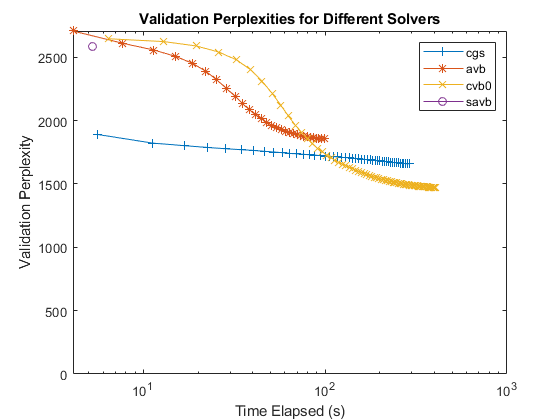

xlabel("Time Elapsed (s)")
ylabel("Validation Perplexity")
ylim([0 inf])
legend(solvers)
title('Validation Perplexities for Different Solvers')

We choose cvb0 as solver since it performs better than the other solvers in estimated perplexities.

#### ***Find optimum number of topics***

Next, we will compare validation perplexities of LDA models with varying numbers of topics to decide the suitable number of topics. 

clear validationPerplexity timeElapsed
numTopicsRange = 10:10:100;
ppl = zeros(numel(numTopicsRange),1);
validationPerplexity = zeros(numel(numTopicsRange), 1);
timeElapsed = zeros(numel(numTopicsRange), 1);
tic
for i = 1:numel(numTopicsRange)
    i
    numTopics = numTopicsRange(i);

    mdl = fitlda(bag,numTopics, ...
        'Solver','cvb0', ...
        'Verbose',0);
    
    [~,validationPerplexity(i)] = logp(mdl,validationData);
    timeElapsed(i) = mdl.FitInfo.History.TimeSinceStart(end);
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

toc

Elapsed time is 11498.631207 seconds.


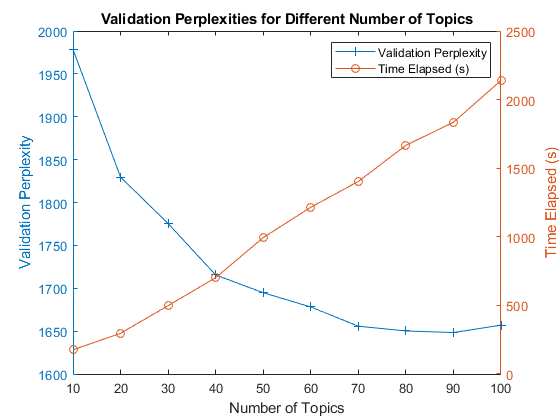

figure
yyaxis left
plot(numTopicsRange,validationPerplexity,'+-')
ylabel("Validation Perplexity")

yyaxis right
plot(numTopicsRange,timeElapsed,'o-')
ylabel("Time Elapsed (s)")

legend(["Validation Perplexity" "Time Elapsed (s)"],'Location','northeast')
xlabel("Number of Topics")
title('Validation Perplexities for Different Number of Topics')

We choose 40 as optimum number of topics by looking at the trade-off between improvements in goodness-of-fit and time taken to fit the models. 

### Final Topic Model

numTopics = 40;
bagAll = bagOfWords(tda);
bagAll = removeInfrequentWords(bagAll,2);
[bagAll,docsRemoved] = removeEmptyDocuments(bagAll); 
mdl = fitlda(bagAll,numTopics, 'Solver','cvb0','IterationLimit',500);

| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |       0.78 |            |  2.259e+04 |        10.000 |             0 |
|          1 |      10.90 | 2.4712e-01 |  3.099e+03 |        10.000 |             0 |
|          2 |      10.89 | 1.6151e-03 |  3.059e+03 |        10.000 |             0 |
|          3 |      10.87 | 1.7849e-03 |  3.016e+03 |        10.000 |             0 |
|          4 |      10.91 | 2.3902e-03 |  2.958e+03 |        10.000 |             0 |
|          5 |      10.91 | 3.4316e-03 |  2.879e+03 |        10.000 |             0 |
|          6 |      11.02 | 4.8263e-03 |  2.771e+03 | 

save('mdl_comm_final.mat', 'mdl') % save model for future analysis

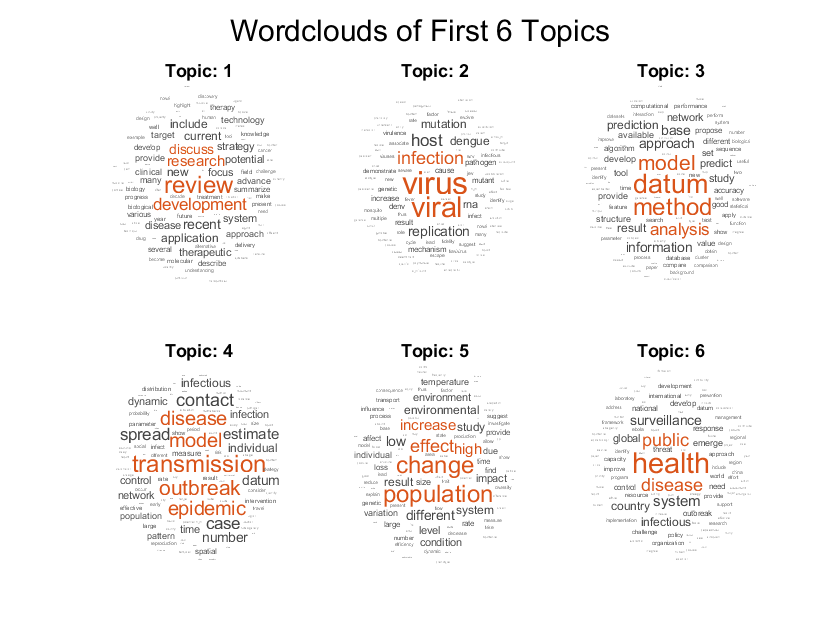

figure;
% plotTopics = randperm(numTopics, 6); % Choose 6 topics to plot
plotTopics = 1:6; % choose first 6 topics to plot
for i = 1:numel(plotTopics)
    subplot(2,3,i)
    wordcloud(mdl,plotTopics(i));
    title("Topic: " + plotTopics(i))
end
sgtitle('Wordclouds of First 6 Topics')

These are wordclouds of 6 topics. The wordclouds show what these topics are mainly about.

## What do we know about transmission?

Next, we will look into the question of what do we know about transmission. Using the final model, we are going to find **the most relevant abstract** for understanding "transmission". This can be done in two steps. 

- Find the topic that has highest probablity for the word "transmission".

AllAbstract = t.Abstract;
AllAbstract(docsRemoved) = [];
AllText = t.Text;
AllText(docsRemoved) = [];
scoresDoc = mdl.DocumentTopicProbabilities;
scoresWord = mdl.TopicWordProbabilities;
transmissionid = find(contains(mdl.Vocabulary, "transmission"));
[maxprobWord,idxTopicTrans] = max(scoresWord(transmissionid, :));

        2. Find the abstract with highest score for the topic.

[maxprobs, idxTopicDoc] = max(scoresDoc(:, idxTopicTrans));
AllAbstract(idxTopicDoc)

ans = "In networks, nodes may preferentially contact other nodes with similar (assortatively mixed) or dissimilar (disassortatively mixed) numbers of contacts. Different patterns of contact support different epidemic dynamics, potentially affecting the efficacy of control measures such as contact tracing, which aims to identify and isolate nodes with infectious contacts. We used stochastic simulations to investigate the effects of mixing patterns on epidemic dynamics and contact-tracing efficacy. For uncontrolled epidemics, outbreaks occur at lower infection rates for more assortatively mixed networks, with faster initial epidemic growth rate and shorter epidemic duration than for disassortatively mixed networks. Contact tracing performs better for assortative mixing where epidemic size is large and tracing rate low, but it performs better for disassortative mixing at higher contact rates. For assortatively mixed networks, disease spreads first to highly connected nodes, but this is ba

`(Copied and pasted for better readability)`

`"In networks, nodes may preferentially contact other nodes with similar (assortatively mixed) or dissimilar (disassortatively mixed) numbers of contacts. Different patterns of contact support different epidemic dynamics, potentially affecting the efficacy of control measures such as contact tracing, which aims to identify and isolate nodes with infectious contacts. We used stochastic simulations to investigate the effects of mixing patterns on epidemic dynamics and contact-tracing efficacy. For uncontrolled epidemics, outbreaks occur at lower infection rates for more assortatively mixed networks, with faster initial epidemic growth rate and shorter epidemic duration than for disassortatively mixed networks. Contact tracing performs better for assortative mixing where epidemic size is large and tracing rate low, but it performs better for disassortative mixing at higher contact rates. For assortatively mixed networks, disease spreads first to highly connected nodes, but this is balanced by contact tracing quickly identifying these same nodes. The converse is true for disassortative mixing, where both disease and tracing are less likely to target highly connected nodes. For small epidemics, contact tracing is more effective on disassortative networks due to the greater resilience of assortative networks to link removal. Multi-step contact tracing is more effective than single-step tracing for assortative mixing, but this effect is smaller for disassortatively mixed networks."`

***Another approach*** would be to get the top abstracts for the topic and then summarize the abstracts (R2020a).

[sortprobs, idxTopicDoc] = sort(scoresDoc(:, idxTopicTrans), 'descend');
idx = 1:5; % top 5 abstracts
selectedAbs = join(AllAbstract(idxTopicDoc(idx)));
str = splitSentences(selectedAbs);
documents = eraseURLs(str);
documents = tokenizedDocument(documents);
documents = regexprep(documents,'[\[ \d \]]','');
lengths = doclength(documents);
idx = lengths < 5;
documents(idx) = [];
str(idx) = [];
scores = lexrankScores(documents);
numSentences = numel(documents);
summarySize = 10; % Limit summary size to 10 sentences
[~,idx] = maxk(scores,summarySize);
summary = join(str(idx), 'descend')

summary = "This is possible if the neighbor is susceptible, recovered, or infected but has not transmitted the disease yet to the root, which happens with probabilities Φ S (t), Φ R (t) and Φ I (t), respectively.descendWe conclude that (1) there is no general predictive formula for the proportion to be traced as there is for the proportion to be vaccinated; (2) variability in time to detection is favourable for effective tracing; (3) tracing effectiveness need not be sensitive to the duration of the latent period and tracing delays; (4) iterative tracing primarily improves effectiveness when single-step tracing is on the brink of being effective.descendThe coefficient of variation of final outbreak size in the subcritical case (R 0 , 1) will be greater than one for any outbreak in which the removal rate is less than approximately 2.41 times the rate of infectious contacts, implying that for many transmissible diseases precise forecasts of the final outbreak size will be unattainable.de

**Conclusion:** Summary of abstracts `(Copied and pasted for better readability)`:

`summary = "This is possible if the neighbor is susceptible, recovered, or infected but has not transmitted the disease yet to the root, which happens with probabilities Φ S (t), Φ R (t) and Φ I (t), respectively. We conclude that (1) there is no general predictive formula for the proportion to be traced as there is for the proportion to be vaccinated; (2) variability in time to detection is favourable for effective tracing; (3) tracing effectiveness need not be sensitive to the duration of the latent period and tracing delays; (4) iterative tracing primarily improves effectiveness when single-step tracing is on the brink of being effective. The coefficient of variation of final outbreak size in the subcritical case (R 0 , 1) will be greater than one for any outbreak in which the removal rate is less than approximately 2.41 times the rate of infectious contacts, implying that for many transmissible diseases precise forecasts of the final outbreak size will be unattainable. θ t Probability that a neighbor of a root node has not transmitted yet the disease to the root node at time t.Φ S (t) Probability that a neighbor of a root node is susceptible at time t.Φ I (t) Probability that an infected neighbor of a root node has not transmitted the disease to the root node at time t.Φ R (t) Probability that a neighbor is recovered at time t without having transmitted the disease to the root node. I studied how the expected final outbreak size and the coefficient of variation in the final size of outbreaks scale with control effectiveness and the rate of infectious contacts in the simple stochastic epidemic. In the EBCM approach, θ t is the probability that a root node has not being infected by a neighbor at time t. We systematically test and compare how the total size of an outbreak differs between these model types depending on the key parameters transmission probability, number of contacts per day, duration of the infectious period, different levels of clustering and varying proportions of repetitive contacts. Multi-step contact tracing is more effective than single-step tracing for assortative mixing, but this effect is smaller for disassortatively mixed networks. In networks, nodes may preferentially contact other nodes with similar (assortatively mixed) or dissimilar (disassortatively mixed) numbers of contacts. Here we deduce from a generic mathematical model how effectiveness of tracing relates to various aspects of time, such as the course of individual infectivity, the (variability in) time between infection and symptom-based detection, and delays in the tracing process."`

This may be too abbreviated to learn anything substantial. The most relevant abstract in the previous section shows more information than the summarized abstracts. 

function t = extractPaperContents(paper)

txt = fileread(paper);
s = jsondecode(txt);

title = "";
if ~isempty(s.metadata) && isfield(s.metadata,'title')
    title = string([s.metadata.title]);
end
abstract = "";
if ~isempty(s.abstract) && isfield(s.abstract,'text')
    abstract = string([s.abstract.text]);
end
text = "";
if ~isempty(s.body_text) && isfield(s.body_text,'text')
    text = string([s.body_text.text]);
end

t = table({s.paper_id},title,abstract,text);
t.Properties.VariableNames = ["ID","Title","Abstract","Text"];
end

function [documents] = preprocessText(textData)
% Convert the text data to lowercase.
textData = lower(textData);

% Tokenize the text.
documents = tokenizedDocument(textData, 'Language', 'en');

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove a list of stop words.
documents = removeStopWords(documents);

% Remove words with 2 or fewer characters, and words with 15 or greater
% characters.
documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);

% Lemmatize the words.
documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','lemma');
end

Copyright 2020 - 2020 The MathWorks, Inc.